## [使用 MATLAB 和 Simulink 仿真 RoadRunner Scenario 的概述](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/overview-of-co-simulating-roadrunner-with-matlab-and-simulink.html)

本主题介绍使用 MATLAB® 和 Simulink® 仿真 RoadRunner 场景的工作流程。RoadRunner 是一款交互式编辑器，可设计用于仿真和测试自动驾驶系统的场景。自动驾驶工具箱™ 提供了一个协同仿真框架，用于使用 MATLAB 和 Simulink 中建模的参与者来仿真 RoadRunner 中的场景。这些是工作流程的步骤：

- 创作 MATLAB System 对象或 Simulink 模型来定义参与者行为。

- RoadRunner 中关联参与者行为。

- （可选）发布参与者行为。

- 调整 MATLAB 或 Simulink 中定义的参数以进行 RoadRunner 仿真。

- 使用 RoadRunner 用户界面仿真场景或通过 MATLAB 以编程方式控制仿真。

- 使用数据记录检查仿真结果。

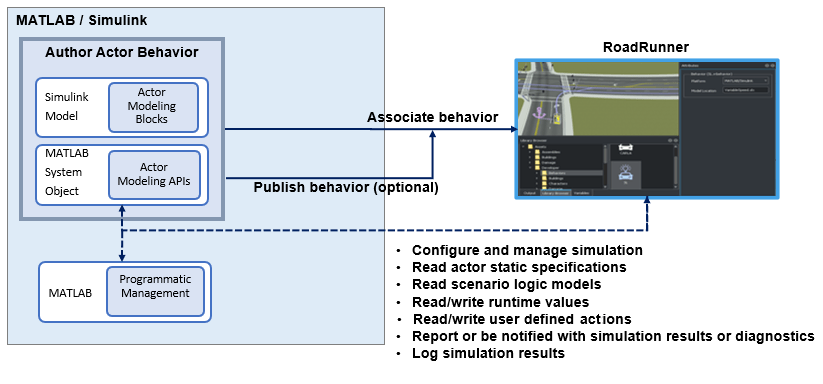

此工作流程假设：

- 已经创建了一个 RoadRunner 项目文件夹。有关详细信息，请参阅 [RoadRunner 项目和场景系统](https://ww2.mathworks.cn/help/releases/R2022b/roadrunner/ug/roadrunner-project-and-scene-system.html)(RoadRunner)。

- 已分别为项目创建并保存了布景文件 `MyExampleScene `和场景文件 `MyExampleScenario`。

## **使用 Simulink 或 MATLAB 系统对象****创作 RoadRunner**** 参与者行为**

可以使用 Simulink 或 MATLAB System object™为 RoadRunner 中的参与者定义自定义行为。

例如，该模型 `SimulinkVehicle.slx `是使用自动驾驶工具箱库中的 Simulink 和 RoadRunner 场景模块创建的。在RoadRunner 场景中，模型读取参与者数据，提高其速度，然后将数据写回到参与者。有关为 RoadRunner 创建 Simulink 行为的更多信息，请参阅[使用 Simulink 中建模的参与者仿真 RoadRunner 场景](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/co-simulate-roadrunner-with-agents-modeled-in-simulink.html)。

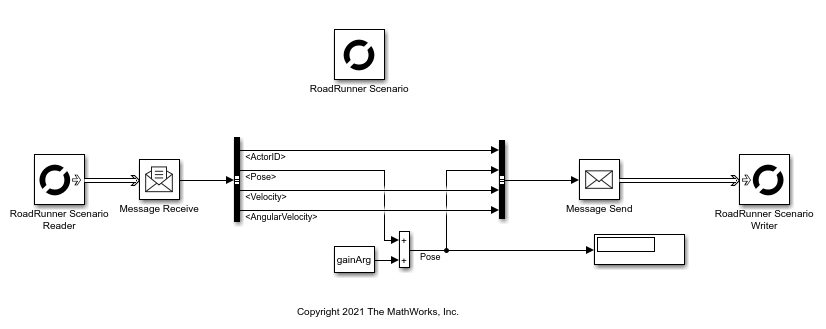

此示例显示创建为 MATLAB System object 文件的 `hVehicle.m `行为。在此行为中，代码读取参与者的初始姿势和速度并更新这些值以使参与者沿着车道行驶。有关使用 MATLAB 创建参与者行为的更多信息，请参阅[使用 MATLAB 中建模的参与者仿真 RoadRunner 场景](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/co-simulate-roadrunner-with-agents-modeled-in-matlab.html)。

    `classdef`` hVehicle < matlab.System`

        `% Copyright 2021 The MathWorks, Inc.`

        `properties`` (Access = private)`

    `        mActorSimulationHdl; `

    `        mScenarioSimulationHdl; `

    `        mActor; `

        `end`

        `methods`` (Access=protected)`

            `function`` sz = getOutputSizeImpl(~)`

    `            sz = [1 1];`

            `end`

            `function`` st = getSampleTimeImpl(obj)`

    `            st = createSampleTime( ``...`

    `                obj, ``'Type'``, ``'Discrete'``, ``'SampleTime'``, 0.02);`

            `end`

            `function`` t = getOutputDataTypeImpl(~)`

    `            t = ``"double"``;`

            `end`

            `function`` resetImpl(~)`

            `end`

            `function`` setupImpl(obj)`

    `            obj.mScenarioSimulationHdl = ``...`

    `                Simulink.ScenarioSimulation.find( ``...`

                        `'ScenarioSimulation'``, ``'SystemObject'``, obj);`

    `            obj.mActorSimulationHdl = Simulink.ScenarioSimulation.find( ``...`

                    `'ActorSimulation'``, ``'SystemObject'``, obj);`

    `            obj.mActor.pose = ``...`

    `                obj.mActorSimulationHdl.getAttribute(``'Pose'``);`

    `            obj.mActor.velocity = ``...`

    `                obj.mActorSimulationHdl.getAttribute(``'Velocity'``);`

            `end`

            `function`` stepImpl(obj, ~)`

    `            velocity = obj.mActor.velocity;`

    `            dTimeUnit = obj.getSampleTimeImpl.SampleTime;`

    `            pose = obj.mActor.pose;`

    `            pose(1,4) = pose(1,4) + velocity(1) * dTimeUnit; ``% x`

    `            pose(2,4) = pose(2,4) + velocity(2) * dTimeUnit; ``% y`

    `            pose(3,4) = pose(3,4) + velocity(3) * dTimeUnit; ``% z`

    `            obj.mActor.pose = pose;`

    `            obj.mActorSimulationHdl.setAttribute(``'Pose'``, pose);`

            `end`

            `function`` releaseImpl(~)`

            `end`

        `end`

    `end`

**在 RoadRunner Scenario 中关联参与者行为**

本节介绍如何将自定义行为与 RoadRunner 中的参与者相关联 。MATLAB 和 Simulink 行为的工作流程相同。

        1. 在RoadRunner场景中，选择“**Library Browser”**，然后选择 `Vehicles `文件夹。然后，右键单击空白区域以创建新行为。对于此步骤，可以选择“**Library Browser”**中的任何文件夹。

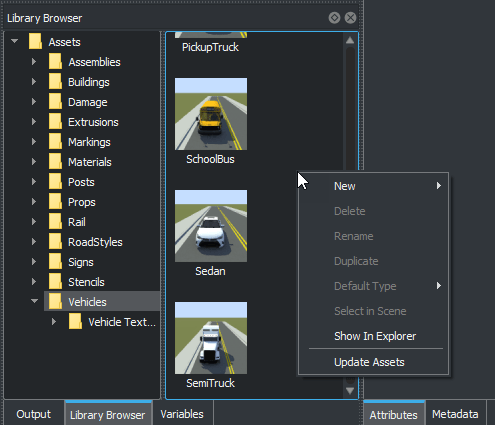

        2. 选择**“New”**，然后选择 **“Behavior”**。

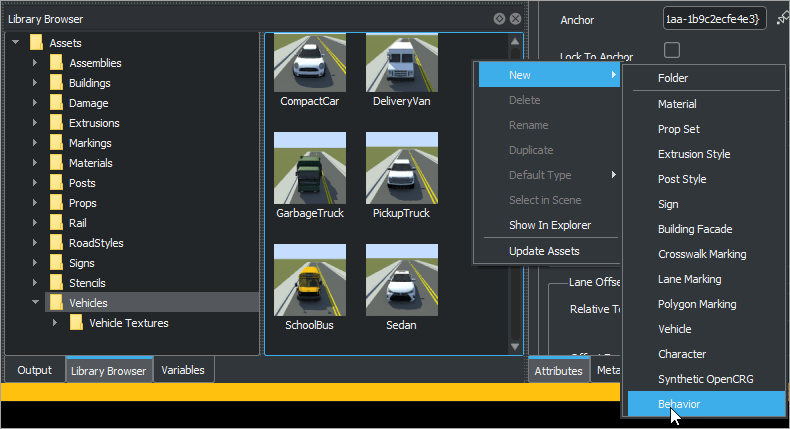

        3. 在“**Attributes”**窗格中，将“**Platform”**设置 为 `MATLAB/Simulink`。使用文件 `hVehicle.m `的位置作为**文件名**。

        如果 Simulink 模型或 MATLAB System object 文件位于工作文件夹中，可以输入文件名及其扩展名 `.slx `或 `.m`，例如 `.m``hVehicle.m`

        还可以使用完整路径输入文件的位置，例如 `MyLocation\hVehicle.m`.

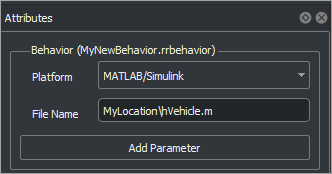

此操作会创建一个新行为，可以将其附加到场景中的参与者。将行为重命名为 `MyNewBehavior`

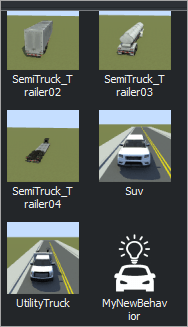

        4. 向场景 `MyExampleScenario` 添加新内容 `CompactCar`。

        5. 要将新行为与参与者关联，请选择 `CompactCar`。在**“Attributes”**窗格的**“Behavior”**框中，通过单击行为图标并将其拖动到框中将行为 `MyNewBehavior` 添加到 `CompactCar`。

## **发布参与者行为**

创建自定义行为后，可以将行为附加到场景中的参与者。或者，可以使用 `Simulink.publish.publishActorBehavior() `和 `Simulink.publish.publishActor()` 函数将参与者行为发布为原型文件或包。

Proto 文件特定于RoadRunner并且具有`.slprotodata`扩展名。该数据接口允许您组合行为模型、其参数及其值，并与RoadRunner共享它们。

您还可以将您的行为发布为文件中的包`.zip`。在文件中发布`.zip`将允许您创建一个包，其中包含原型文件以及模型的其他支持文件。

有关行为发布工作流程的更多信息，请参阅[将 Actor 行为发布为原始文件、包或操作资产](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/publish-actor-behavior-as-a-proto-file-or-a-package.html)。**调整 Actor 参数**

您可以调整为RoadRunner中的自定义 MATLAB 和 Simulink 行为定义的参数。

例如，假设您有一个`foo01.slx`带有增益参数 的 Simulink 模型`gain01`。参数值为`2`。您可以通过两种不同的方式关联模型来调整RoadRunner中的模型参数。

- 您可以将模型发布为原型文件并在RoadRunner中调整参数 。

- 您可以直接将 MATLAB 或 Simulink 模型与RoadRunner中的行为关联，然后调整RoadRunner中的参数。

**调整RoadRunner****中原型文件的参数**

将模型发布为原型文件`foo01.slprotodata`. 发布的原型文件包含模型、参数和值。有关更多信息，请参阅[将 Actor 行为发布为原始文件、包或操作资产](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/publish-actor-behavior-as-a-proto-file-or-a-package.html)。

`gain01`要在RoadRunner场景中调整参数：

- 将`foo01.slprotodata`proto 文件拖到 下的任意文件夹中`MyProject/Assets`。

- 双击行为`foo01`并观察增益参数及其值出现在RoadRunner中。该显示对于参数值是只读的。要调整参数，请继续执行以下步骤。

- 将原型文件附加到您场景中的车辆。

- 选择 的操作阶段`Sedan`并单击 **添加操作**。然后，选择`Change Behavior Parameter`。

- 观察模型参数`gain01`出现。您现在可以调整模拟参数。

**调整与行为相关的模型参数，无需发布**

您还可以将 Simulink 行为直接关联到场景中的参与者，而无需发布。

在这种情况下，您创建一个新行为，然后向您的行为添加一个新参数，其名称与 Simulink 参数 相同`gain01`。然后，您无需任何额外步骤即可调整参数。

- 按照前面的步骤创建新行为。

- 选择**添加参数**。

- 创建与模型参数同名的参数 `gain01`。

- 工作流程的其余部分与发布文件时相同。将行为附加到您的车辆，然后从操作阶段调整模拟参数。

**在RoadRunner****中模拟场景**

使用RoadRunner中的场景编辑器通过自定义行为模拟您的场景，并控制模拟的进度并执行开始、暂停、单步、继续、停止操作。

为了支持定义为 Simulink 模型或 MATLAB System object 的自定义行为的仿真，您需要配置RoadRunner，以便它可以找到您计算机上可用的 MATLAB 安装。

配置文件：

- 打开RoadRunner`SimulationConfiguration.xml`安装时生成的文件。有关更多信息，请参阅[模拟配置](https://ww2.mathworks.cn/help/releases/R2022b/roadrunner-scenario/ref/simulationconfiguration.html)（RoadRunner 场景）。

- 在该文件中，搜索与MATLAB平台相关的配置（参见下面的示例）。`        <平台名称= ``“MATLAB”`` >  `

`            <ExecutablePath>C:\Program Files\MATLAB\R2022a\matlab\bin\matlab.exe</ExecutablePath>`

`            <StartTimeOut>60000</StartTimeOut>`

`            <无桌面>��true</无桌面>  `

`        </平台>`

- 将 MATLAB 可执行文件的完整路径（由标记表示`<ExecutablePath>` ）替换为计算机上已安装的可执行文件。

您还可以控制仿真的速度和仿真步长，并在仿真过程中观察当前的仿真时间。

## **使用 MATLAB 进行控制场景仿真**

还可以使用 MATLAB 来控制仿真，而不是使用 RoadRunner 中的场景编辑器。

- 启动 RoadRunner 和 RoadRunner Scenario。有关详细信息，请参阅 [`roadrunner`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/roadrunner.html)。

- 加载并保存预定义的场景文件 ( `.rrScenario`)。有关详细信息，请参阅 [`openScenario`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/roadrunner.openscenario.html) 和 [`saveScenario`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/roadrunner.savescenario.html)。

- 配置和管理模拟。有关详细信息，请参阅 [`Simulink.ScenarioSimulation`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/simulink.scenariosimulation.html)。

- 在 MATLAB 中，通过获取或设置仿真步长和仿真速度来准备仿真。

- 使用 MATLAB 控制仿真并开始、停止、暂停、恢复和单步。

- 获取当前播放状态。

- 使用 MATLAB 函数和 MATLAB System 对象。

- 阅读参与者静态规范或场景逻辑模型。有关详细信息，请参阅 [`Simulink.ActorModel`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/simulink.actormodel.html)。

- 读取和写入运行时值，例如参与者运行时属性，有关详细信息，请参阅 [`Simulink.ActorSimulation`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/simulink.actorsimulation.html)。

- 报告模拟结果和诊断（例如警告和错误）或收到通知，或接收和发送场景逻辑事件。有关详细信息，请参阅 [`Simulink.ScenarioSimulation`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/simulink.scenariosimulation.html)。

此示例演示如何使用 MATLAB 代码仿真场景。每个步骤完成后，等待 RoadRunner 或 MATLAB 的预期响应，然后再继续下一步。

        1. 使用这些命令指定RoadRunner 安装文件夹的路径 `MyInstallationFolder`，并仅在第一次 MATLAB 安装时创建 MATLAB 和 RoadRunner 之间的连接。`RRInstallationFolder = ``"我的安装文件夹"`` ;`

RRInstallationFolder = "MyInstallationFolder";
s = settings;
s.roadrunner.application.InstallationFolder.PersonalValue = RRInstallationFolder; 
s.roadrunner.application.InstallationFolder.TemporaryValue = RRInstallationFolder;

        2. 要更改RoadRunner Scenario和 MATLAB之间连接的超时值，请将所需的超时值（以秒为单位）分配给该 `Timeout `设置。

s.roadrunner.application.Timeout.TemporaryValue = 10;

实际超时值是指定值和每个事件类型的默认值中的较大者。有关更多信息，请参阅[超时值](https://ww2.mathworks.cn/help/releases/R2022b/roadrunner-scenario/ref/simulationconfiguration.html#mw_68370398-1324-4a9c-a6b2-e985ba0e81e7)（RoadRunner Scenario）。

        3. 要从 MATLAB打开RoadRunner项目，请使用此命令。

rrapp = roadrunner('MyProjectLocation');

        4. 打开场景`MyExampleScene`。

rrapp.openScene('MyExampleScene');

        5. 打开场景`MyExampleScenario`。

rrapp.openScenario('MyExampleScenario');

        6. 从 MATLAB 获取仿真对象来控制仿真。

ss = rrapp.createSimulation();

        7. 从命令行启动模拟。

ss.set('SimulationCommand','Start');

## **使用数据记录检查仿真结果**

可以使用数据记录检查仿真结果。此示例代码记录仿真数据，运行仿真，然后获取记录的仿真数据。有关日志记录的更多信息，请参阅 [`Simulink.ScenarioLog`](https://ww2.mathworks.cn/help/releases/R2022b/driving/ref/simulink.scenariolog.html)。

% 打开日志记录
ss.set('Logging', 'On')
 
% 运行模拟
ss.set('SimulationCommand', 'Start')
 
% 获取记录的模拟数据
log = ss.get('SimulationLog');

使用 MATLAB 控制场景仿真并使用数据记录检查结果假定手动打开 MATLAB 会话来控制仿真。如果在仿真开始之前没有任何活动的 MATLAB 会话连接到 RoadRunner，RoadRunner会自动打开 MATLAB 会话以使用 MATLAB 或 Simulink 参与者仿真场景。

要启用此功能，请通过将 ExecutablePath 参数设置 [为](https://ww2.mathworks.cn/help/releases/R2022b/roadrunner-scenario/ref/simulationconfiguration.html) MATLAB 可执行文件并在启动 RoadRunner 之前正确设置 StartTimeOut 参数来配置**模拟**配置（**RoadRunner Scenario**）。

## 相关话题

- [使用 Simulink 中建模的 Actor 模拟 RoadRunner 场景](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/co-simulate-roadrunner-with-agents-modeled-in-simulink.html)

- [使用 MATLAB 中建模的 Actor 模拟 RoadRunner 场景](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/co-simulate-roadrunner-with-agents-modeled-in-matlab.html)

- [将 Actor 行为发布为原始文件、包或动作资产](https://ww2.mathworks.cn/help/releases/R2022b/driving/ug/publish-actor-behavior-as-a-proto-file-or-a-package.html)